## Dimensionering af Lejer

### Opgave 1

En aksel med en diameter på 7 mm roterer med en hastighed på 2900 r/min.

Den er ophængt i to SKF single row deep groove ball bearings: 627. Beregn den nominelle levetid i henhold til ISO for et af lejerne, når det udsættes for:

(a) en ren radial kraft på 500 N.

(b) en ren aksial kraft på 500 N.

(c) en diagonal kraft på 500 N. ($F_r = F_a$)

(a)

Fra SKF s. 89 har vi et af lejernes levetid som

$L_{10} ={\left(\frac{C}{P}\right)}^p$ og $L_{10h} =\frac{{10}^6 }{60n}L_{10}$

Eftersom vi arbejder med et kugleleje og ikke et rulleleje er $p = 3$, så


$$L_{10} ={\left(\frac{C}{P}\right)}^3$$


For SKF627 har vi den nominelle statiske belastning $C = 3.45 kN$ (s. 262).

Nu mangler vi blot at finde den ækvivalente dynamiske lejebelastning $P$.

På s. 254 ser vi at $P$ afhænger af forholdet mellem den aksielle kraft $F_a$ og den radielle kraft $F_r$.

Her har vi


$$F_a/F_r = 0/500 = 0$$


Eftersom $0 < e$ (hvor $e$ er det begrænsende lastforhold) har vi at $P = F_r$ (s. 254). 

(b)

Her har vi

$F_a/F_r \to \infty$ og dermed $F_a/F_r > e$, hvilket betyder at $P = X F_r + Y F_a$ (s. 254). X og Y-værdien her findes i tabel 9 (s. 257)

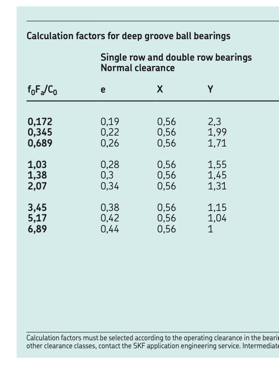

clear; close all; clc;

n = 2900; %opgave
Fa = [0; 0.5; 0.5 * sqrt(2)/2];
Fr = [0.5; 0; 0.5 * sqrt(2)/2];
name = ["(a)", "(b)", "(c)"];

%data for SKF627
C0 = 1.37; %s. 262
C = 3.45;  %s. 262
f0 = 12;   %s. 262
p = 3;     %s. 89

%Tabel 9 (karakteristiske beregningsværdier s. 257)
t = [0.172; 0.345; 0.689; 1.03; 1.38; 2.07; 3.45; 5.17; 6.89];
e            = [0.19;  0.22;  0.26;  0.28; 0.30; 0.34; 0.38; 0.42; 0.44];
X            = [0.56;  0.56;  0.56;  0.56; 0.56; 0.56; 0.56; 0.56; 0.56];
Y            = [2.30;  1.99;  1.71;  1.55; 1.45; 1.31; 1.15; 1.04; 1.00];

T = table(t, e, X, Y);

for i = 1:3
    Fr_i = Fr(i);
    Fa_i = Fa(i);

    % Find P
    if Fa_i == 0
        P = Fr_i;                 % ren radial
    else
        f0F = f0*Fa_i/C0
        e_i = interp1(t, e, f0F);  % lineær interpolation
        X_i = interp1(t, X, f0F);
        Y_i = interp1(t, Y, f0F);

        if Fr_i == 0
            P = Y_i * Fa_i;        % ren aksial (X*Fr=0)
        else
            if (Fa_i/Fr_i) <= e_i
                P = Fr_i;
            else
                P = X_i*Fr_i + Y_i*Fa_i;
            end
        end
    end

    % Levetid
    L10  = (C/P)^p;
    L10h = 1e6/(60*n) * L10;

    fprintf("\n=== Levetid for leje i %s ===\n", name(i));
    fprintf("P       = %.4f kN\n", P);
    fprintf("L_10    = %.2f * 10^6 omdr\n", L10);
    fprintf("L_10h   = %.2f timer\n", L10h);
end    


=== Levetid for leje i (a) ===


P       = 0.5000 kN


L_10    = 328.51 * 10^6 omdr


L_10h   = 1887.98 timer


f0F = 4.3796


=== Levetid for leje i (b) ===


P       = 0.5453 kN


L_10    = 253.28 * 10^6 omdr


L_10h   = 1455.66 timer


f0F = 3.0968


=== Levetid for leje i (c) ===


P       = 0.6191 kN


L_10    = 173.09 * 10^6 omdr


L_10h   = 994.77 timer


### Opgave 2

Vælg et cylindrisk rulleleje med en huldiameter på 100 mm, der skal overføre en radial belastning $F_r = 12500 N$ ved en hastighed på 1250 r/min. Lejet skal have en nominel levetid på 40000 timer i henhold til ISO formel for nominel levetid (SKF side 89).

ISO formel for nominel levetid er:

$L_{10h} =\frac{{10}^6 }{60n}L_{10}$, hvor $L_{10} ={\left(\frac{C}{P}\right)}^p$ 

Vi isolerer for den nødvendige C og får:


$$\;C=P\cdot {\left(L_{10} \right)}^{\frac{1}{p}}$$



$$C=P\cdot {\left(\frac{L_{10h} \cdot 60n}{{10}^6 }\right)}^{\frac{1}{p}}$$
 

%Opgavedata
L10h = 40000;
n = 1250;
d = 0.1;
Fr = 12.5;

p = 10/3; %for rulleleje, s. 89
P = Fr; %s. 509

CRequired = P * ((L10h * 60 * n)/(10^6))^(1/p);

C = [85.8; 285; 285; 285; 285; 380; 380; 380; 450; 450; 450; 450; 670; 670; 670; 457];
M = [1.45; 3.35; 3.45; 3.45; 3.6; 4.75; 4.8; 4.8; 7.35; 7.45; 7.65; 7.7; 12; 12; 12.5; 15.5];
designation = ["NU 1020 ML"; "NU 220 ECP"; "N 220 ECP"; "NJ 220 ECP"; "NUP 220 ECP"; "NU 2220 ECP"; "NJ 2220 ECP"; "NUP 2220 ECP"; "N 320 ECP"; "NU 320 ECP"; "NJ 320 ECJ"; "NUP 320 ECJ"; "NJ 2320 ECJ"; "NU 2320 ECP"; "NUP 2320 ECJ"; "NU 420 M"];
T = table(C, M, designation);

% --- Filtrér lejer der overholder kravet ---
ok = T.C >= CRequired;
T_ok = T(ok, :);

fprintf("C_required = %.3f\n\n", CRequired);

C_required = 138.053




fprintf("De %.0f lejer der overholder stykrekravet (C >= C_required):\n", height(T_ok));

De 15 lejer der overholder stykrekravet (C >= C_required):


disp(T_ok)

     C      M       designation  
    ___    ____    ______________

    285    3.35    "NU 220 ECP"  
    285    3.45    "N 220 ECP"   
    285    3.45    "NJ 220 ECP"  
    285     3.6    "NUP 220 ECP" 
    380    4.75    "NU 2220 ECP" 
    380     4.8    "NJ 2220 ECP" 
    380     4.8    "NUP 2220 ECP"
    450    7.35    "N 320 ECP"   
    450    7.45    "NU 320 ECP"  
    450    7.65    "NJ 320 ECJ"  
    450     7.7    "NUP 320 ECJ" 
    670      12    "NJ 2320 ECJ" 
    670      12    "NU 2320 ECP" 
    670    12.5    "NUP 2320 ECJ"
    457    15.5    "NU 420 M"    




% --- Find mindste masse blandt dem ---
[~, idxLocal] = min(T_ok.M);
best = T_ok(idxLocal, :);

fprintf("Mindste masse blandt godkendte lejer:\n");

Mindste masse blandt godkendte lejer:


fprintf("  Designation: %s\n", best.designation);

  Designation: NU 220 ECP


fprintf("  C = %.3f\n", best.C);

  C = 285.000


fprintf("  M = %.3f\n", best.M);

  M = 3.350


### Opgave 3

Beregn den nominelle levetid for et sfærisk kugleleje 1212 ETN9 i henhold til ISO's formel for nominel levetid (SKF side 89)

Den kører med 4.000 r/min og udsættes for en aksial belastning 250 N.

Den radiale komponent, $F_r$, varierer. 60% af driftstiden er 750N og 40% af tiden 1500N.

ISO formel for nominel levetid er:

$L_{10h} =\frac{{10}^6 }{60n}L_{10}$, hvor $L_{10} ={\left(\frac{C}{P}\right)}^p$ 

For variabel belastning har vi i øvrigt (s. 90):


$$L_{10m} =\frac{1}{\frac{U_1 }{L_{10\mathrm{m1}} }+\frac{U_2 }{L_{10\mathrm{m2}} }+\ldots\;}$$


I øvrigt har vi (s. 445):

$\frac{F_a }{F_r }\le e\;$=> $P=F_r +Y_1 F_a$

$\frac{F_a }{F_r }>e$=> $P=0\ldotp 65\;F_r +Y_2 F_a$

Data for kuglelejet er på s. 454-455.

%Opgavedata
n = 4000;
Fa = 0.250;
Fr = [0.75; 1.5];
U = [0.6; 0.4];
p = 3;

%Kuglelejedata (s. 454-455)
l.D = 0.11;
l.B = 0.022;
l.C = 31.2;
l.C0 = 12.2;
l.Pu = 0.62;
l.M = 0.9;
l.designation = "1212 ETN9";

l.d1 = 0.078;
l.d2 = l.d1;
l.D1 = 0.0956;
l.D2 = l.D1;
l.k_r = 0.04;
l.e = 0.19;
l.Y1 = 3.3;
l.Y2 = 5.1;
l.Y0 = 3.6;

for i = 1:2
    lastForhold = Fa/Fr(i);

    if lastForhold <= l.e
        P(i) = Fr(i) + l.Y1 * Fa;
    else
        P(i) = 0.65 * Fr(i) + l.Y2 * Fa;
    end

    L_10m(i) = (l.C/P(i))^(p);
end

L10m = 1 / sum(U ./ L_10m(:));

L10h = 10^6 * L10m / (60 * n);

fprintf("Altså holder kuglejet i %.3f timer, \ntilsvarende %.3f millioner omdrejninger", L10h, L10m);

Altså holder kuglejet i 15224.170 timer, 
tilsvarende 3653.801 millioner omdrejninger